# Create Simple Image Classification Network

This example shows how to create and train a simple convolutional neural network for deep learning classification. Convolutional neural networks are essential tools for deep learning and are especially suited for image recognition.

The example demonstrates how to: 

- Load image data.

- Define the network architecture.

- Specify training options.

- Train the network.

- Predict the labels of new data and calculate the classification accuracy.

## Load Data

Download and create the medMNIST image datastore. The `imageDatastore` function automatically labels the images based on folder names.

pneumoniadata = readmedmnist("pneumonia");

Completed download in 0.37981 seconds. 
Extracting: train_images structure. 
Extracting: train_labels structure. 


save_path = "./pneumodataset";
mkdir(save_path);
imds = createmedmnistdatastore(pneumoniadata.train_images, pneumoniadata.train_labels, "savepath", save_path);

Divide the data into training and validation data sets, so that each category in the training set contains 1214 images, and the validation set contains the remaining images from each label. `splitEachLabel` splits the image datastore into two new datastores for training and validation.

numTrainFiles = 1214;
[imdsTrain, imdsValidation] = splitEachLabel(imds, numTrainFiles, "randomized");

View the class names.

classNames = categories(imdsTrain.Labels)

classNames = 2×1 cell array
    {'0'}
    {'1'}


## Define Network Architecture

Define the convolutional neural network architecture. Specify the size of the images in the input layer of the network and the number of classes in the fully connected layer. Each image is 28-by-28-by-3 pixels and there are 7 classes.

inputSize = [28 28 1];
numClasses = 2;

layers = [
    imageInputLayer(inputSize)
    convolution2dLayer(5,20)
    batchNormalizationLayer
    reluLayer
    fullyConnectedLayer(numClasses)
    softmaxLayer];

For more information about deep learning layers, see [List of Deep Learning Layers](docid:nnet_ug#mw_25a9e4c2-614f-48b9-97e2-bbdd7aaf906f).

## Specify Training Options

Specify the training options. Choosing among the options requires empirical analysis. To explore different training option configurations by running experiments, you can use the [Experiment Manager](docid:nnet_ref#mw_11ce840f-eed7-4975-9c28-baeebd79f092) app. 

options = trainingOptions("sgdm", ...
    MaxEpochs=4, ...
    ValidationData=imdsValidation, ...
    ValidationFrequency=30, ...
    Plots="training-progress", ...
    Metrics="accuracy", ...
    Verbose=false);

## Train Neural Network

Train the neural network using the [`trainnet`](docid:nnet_ref.mw_87a4761c-af20-4e6e-9752-e145a8295c97) function. For classification, use cross-entropy loss. By default, the `trainnet` function uses a GPU if one is available. Using a GPU requires a Parallel Computing Toolbox™ license and a supported GPU device. For information on supported devices, see [GPU Computing Requirements](docid:distcomp_ug.mw_57e04559-0b60-42d5-ad55-e77ec5f5865f). Otherwise, the function uses the CPU. To specify the execution environment, use the `ExecutionEnvironment` training option.

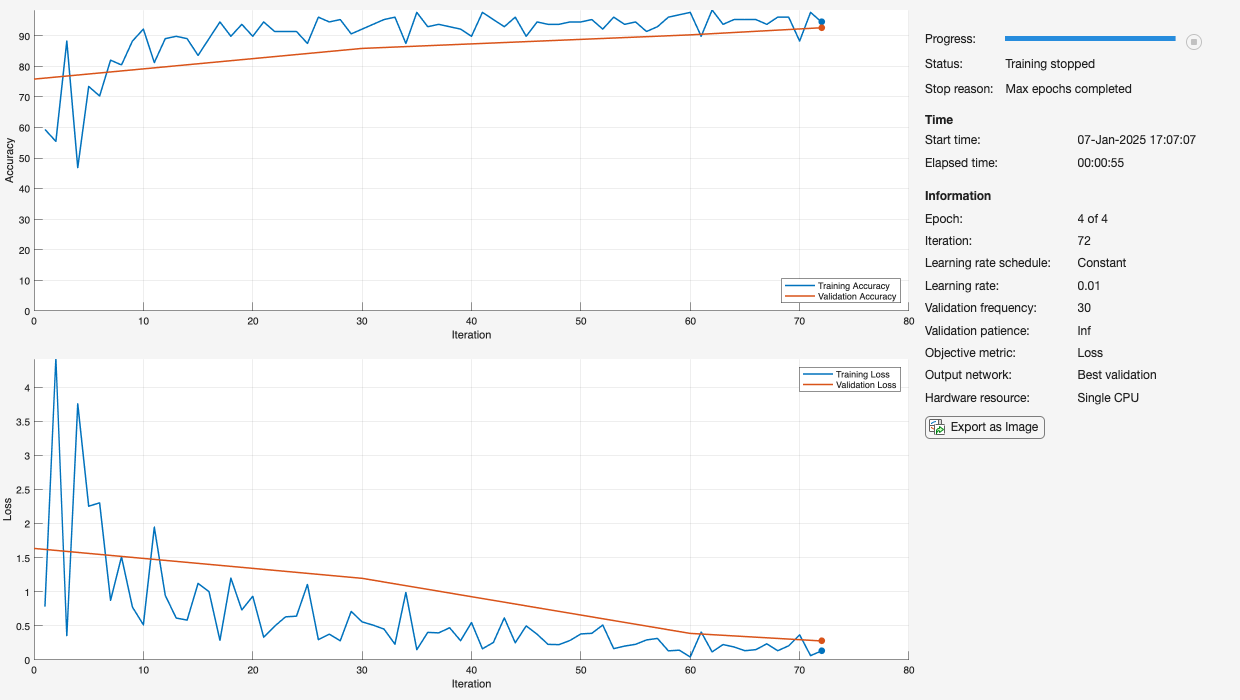

net = trainnet(imdsTrain, layers, "crossentropy", options);

## Test Neural Network

To test the neural network, classify the validation data and calculate the classification accuracy. 

Test the neural network using the [`testnet`](docid:nnet_ref.mw_3eb84788-36da-4e3e-a351-ecbc55b86c2b) function. For single-label classification, evaluate the accuracy. The accuracy is the percentage of correct predictions. By default, the `testnet` function uses a GPU if one is available. To select the execution environment manually, use the `ExecutionEnvironment` argument of the `testnet` function.

accuracy = testnet(net, imdsValidation, "accuracy")

accuracy = 92.6316

For next steps in deep learning, you can try using pretrained network for other tasks. Solve new classification problems on your image data with transfer learning or feature extraction. For examples, see [Start Deep Learning Faster Using Transfer Learning](docid:nnet_ug#bvmv5y4) and [Train Classifiers Using Features Extracted from Pretrained Networks](docid:nnet_ug#bvnmbbq-1). To learn more about pretrained networks, see [Pretrained Deep Neural Networks](docid:nnet_ug#bvf9ych-1).

*Copyright 2018-2024 The MathWorks, Inc.*